%alles loaden
load lengte.mat
load test1.mat
load test2.mat
load test3.mat

f = [f1; f2; f3];
lSI = l * 0.01;
figure(1)
hold on
legends = {};
vc = 0;
%for loop voor alle metingen te plotten
for j=1:3
    
    kracht = f(j,:);
    scatter(lSI,kracht,'x')
    fitj = fit(lSI',kracht', "poly1")
    plot(fitj)
    legends = [legends {"metingen reeks " + j, "fitted curve reeks " + j}];
    %plot(fitj, lSI, kracht)
    disp("de veerconstante is: ")
    disp(fitj.p1 + "N/m")
    vc = vc + fitj.p1;
end

fitj =      Linear model Poly1:
     fitj(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       183.8  (175.8, 191.9)
       p2 =      -3.001  (-3.589, -2.413)

de veerconstante is: 


183.8415N/m


fitj =      Linear model Poly1:
     fitj(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       186.8  (182.5, 191)
       p2 =       -3.14  (-3.451, -2.83)

de veerconstante is: 


186.7683N/m


fitj =      Linear model Poly1:
     fitj(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =         190  (182.1, 197.9)
       p2 =        -3.3  (-3.871, -2.729)

de veerconstante is: 


190N/m


%plot settings
ax = gca

ax =   Axes with properties:

             XLim: [0.0300 0.1000]
             YLim: [2 16]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1120 0.7750 0.8130]
            Units: 'normalized'

  Show all properties


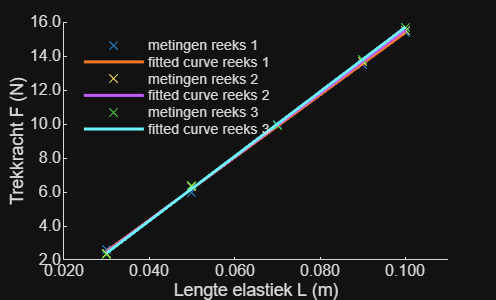

xtickformat('%.3f');
ytickformat('%.1f' );
ax.FontSize = 8;
xlim([lSI(1)-0.01 lSI(end) + 0.01]);
legend(legends)
xlabel('Lengte elastiek L (m)' );
ylabel('Trekkracht F (N)' );
legend('Location' ,'northwest' );
legend('boxoff' );

vc = vc/height(f);
disp("de veerconstante(gem) is: ")

de veerconstante(gem) is: 


disp(vc + "N/m")

186.8699N/m
